clearvars
format shortEng

freq = 50;
T = 1/freq;

percents = [0 20 40 60 80 100] % corresponding to the measurements

percents =      0.0000e+000    20.0000e+000    40.0000e+000    60.0000e+000    80.0000e+000   100.0000e+000


% experimental RPM measurement with HTI HT522 Tachometer
rpms = [0 5000, 7300, 8420, 9220, 10200]

rpms =      0.0000e+000     5.0000e+003     7.3000e+003     8.4200e+003     9.2200e+003    10.2000e+003


fittedPoly = polyfit(percents, rpms, 3)

fittedPoly =     19.6528e-003    -4.1131e+000   316.7579e+000    37.6190e+000


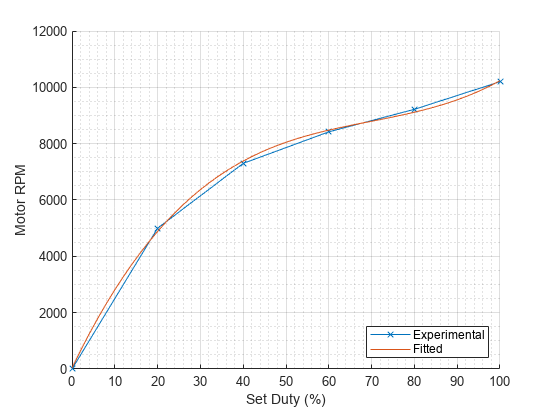


theoPercents = 0:2:100;
theoRpms = polyval(fittedPoly, theoPercents);

figure()
hold on
grid on
grid minor
plot(percents, rpms, "x-")
plot(theoPercents, theoRpms)
xlabel("Set Duty (%)")
ylabel("Motor RPM")
legend("Experimental", "Fitted", Location="southeast")
hold off
saveas(gcf, "graph_duty.png")


%% Expected RPM at maximum using KV
motorKV = 1100;
appliedvoltage = 9;
expectedMaxRPM = motorKV*appliedvoltage

expectedMaxRPM =      9.9000e+003



thousands = percents*10 % corresponding to the measurements

thousands =      0.0000e+000   200.0000e+000   400.0000e+000   600.0000e+000   800.0000e+000     1.0000e+003


% experimental RPM measurement with HTI HT522 Tachometer
% rpms = [4600, 7300, 8420, 9220, 10200]
fittedPoly = polyfit(thousands, rpms, 3)

fittedPoly =     19.6528e-006   -41.1310e-003    31.6758e+000    37.6190e+000


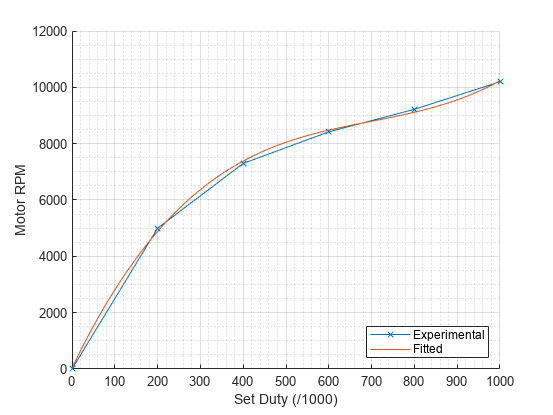


theoThosands = 0:2:1000;
theoRpms = polyval(fittedPoly, theoThosands);

figure()
hold on
grid on
grid minor
plot(thousands, rpms, "x-")
plot(theoThosands, theoRpms)
xlabel("Set Duty (/1000)")
ylabel("Motor RPM")
legend("Experimental", "Fitted", Location="southeast")
hold off
saveas(gcf, "graph_duty_thosand.png")


%% Expected RPM at maximum using KV
motorKV = 1100;
appliedvoltage = 9;
expectedMaxRPM = motorKV*appliedvoltage

expectedMaxRPM =      9.9000e+003


syms x y
y = poly2sym(fittedPoly)

$$y = \frac{5800476192066451\,x^{3}}{295147905179352825856}-\frac{691\,x^{2}}{16800}+\frac{79823\,x}{2520}+\frac{5294410276223843}{140737488355328}$$

finv = matlabFunction(finverse(y))

finv = function_handle with value:
    @(x)1.0./(x.*2.544169611307419e+4+sqrt((x.*2.544169611307419e+4-2.236410629423207e+8).^2+1.293484973688578e+14)-2.236410629423207e+8).^(1.0./3.0).*(-5.057320329772607e+4)+(x.*2.544169611307419e+4+sqrt((x.*2.544169611307419e+4-2.236410629423207e+8).^2+1.293484973688578e+14)-2.236410629423207e+8).^(1.0./3.0)+6.976274608783439e+2


finv(9000)

ans =    765.8511e+000


getDuty = finv

getDuty = function_handle with value:
    @(x)1.0./(x.*2.544169611307419e+4+sqrt((x.*2.544169611307419e+4-2.236410629423207e+8).^2+1.293484973688578e+14)-2.236410629423207e+8).^(1.0./3.0).*(-5.057320329772607e+4)+(x.*2.544169611307419e+4+sqrt((x.*2.544169611307419e+4-2.236410629423207e+8).^2+1.293484973688578e+14)-2.236410629423207e+8).^(1.0./3.0)+6.976274608783439e+2


% fittedPolyInverse = polyfit(rpms, thousands, 3)
% theoRpms = 0:50:10e3
% theoThosands = polyval(fittedPolyInverse, theoRpms)
% figure()
% hold on
% grid on
% grid minor
% plot(thousands, rpms, "x-")
% plot(theoThosands, theoRpms)
% xlabel("Set Duty (/1000)")
% ylabel("Motor RPM")
% legend("Experimental", "Fitted", Location="southeast")
% hold off
% saveas(gcf, "graph_duty_thosand_inverse.png")